port = "COM15";

baudrate = 9600;

s = serialport(port,baudrate);

pan = [];

tilt = [];

dist = [];

for i = 1:1300

    values = eval(strcat('[',readline(s),']'));

    pan(end+1) = values(1);

    tilt(end+1) = values(2);
end

pan

pan =     70    69    68    67    66    65    64    63    62    61    60    59    58    57    56    55    54    53    52    51    50    49    48    47    46    45    44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    20    21    22    23    24    25    26    27    28



tilt

tilt =     50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    50    51    51    51    51    51    51    51    51    51



dist

dist =     21     0     0     0     0   136     0     0   138   119   147     0     0   141   136   138   121   143     0   130   117     0   108   134   130   136   141   109   138   143   143     0     0   136   119     0   143     0     0     0   141     0   143     0     0     0     0     0   123    90


tilt = 110 - tilt

tilt =     60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    60    59    59    59    59    59    59    59    59    59



rad_pan = deg2rad(pan);
rad_tilt = deg2rad(tilt);
matrix = [rad_pan ; rad_tilt ; dist]

matrix =     1.2217    1.2043    1.1868    1.1694    1.1519    1.1345    1.1170    1.0996    1.0821    1.0647    1.0472    1.0297    1.0123    0.9948    0.9774    0.9599    0.9425    0.9250    0.9076    0.8901    0.8727    0.8552    0.8378    0.8203    0.8029    0.7854    0.7679    0.7505    0.7330    0.7156    0.6981    0.6807    0.6632    0.6458    0.6283    0.6109    0.5934    0.5760    0.5585    0.5411    0.5236    0.3491    0.3665    0.3840    0.4014    0.4189    0.4363    0.4538    0.4712    0.4887
    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0297    1.0297    1.0297    1.0297    1.0297    1.0297    1.0297    1.0297

filtered_matrix = []


filtered_matrix =

     []



for i = 1: length(matrix)
    if matrix(3,i) ~= 0
        filtered_matrix(:,end+1) = matrix(:,i);
    end
end


far_points = [];
mid_points = [];
close_points = [];
for i = 1: length(filtered_matrix)
    if filtered_matrix(3,i) >= 100
        far_points(:,end+1) = filtered_matrix(:,i);
    elseif filtered_matrix(3,i) > 50 && filtered_matrix(3,i) < 100
        mid_points(:,end+1) = filtered_matrix(:,i);
    else
        close_points(:,end+1) = filtered_matrix(:,i);
    end
end

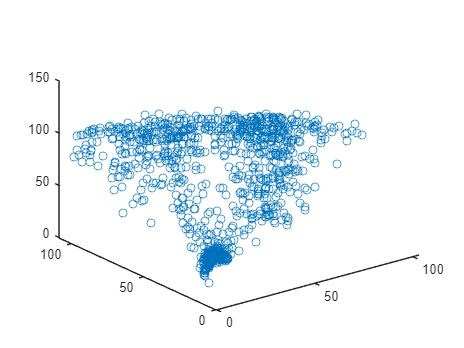

figure()
[x,y,z] = sph2cart(filtered_matrix(1,:), filtered_matrix(2,:), filtered_matrix(3,:));
plot3(x,y,z,'o')
hold off

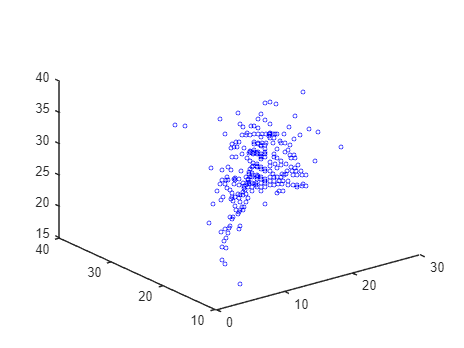

figure()
[x_mid,y_mid,z_mid] = sph2cart(mid_points(1,:), mid_points(2,:), mid_points(3,:));
[x_small,y_small,z_small] = sph2cart(close_points(1,:), close_points(2,:), close_points(3,:));
plot3(x_small,y_small,z_small,'bo','MarkerSize',3)